P = tf([1],[1,1,0])

P =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.



fprintf('----Original root locus----');

----Original root locus----

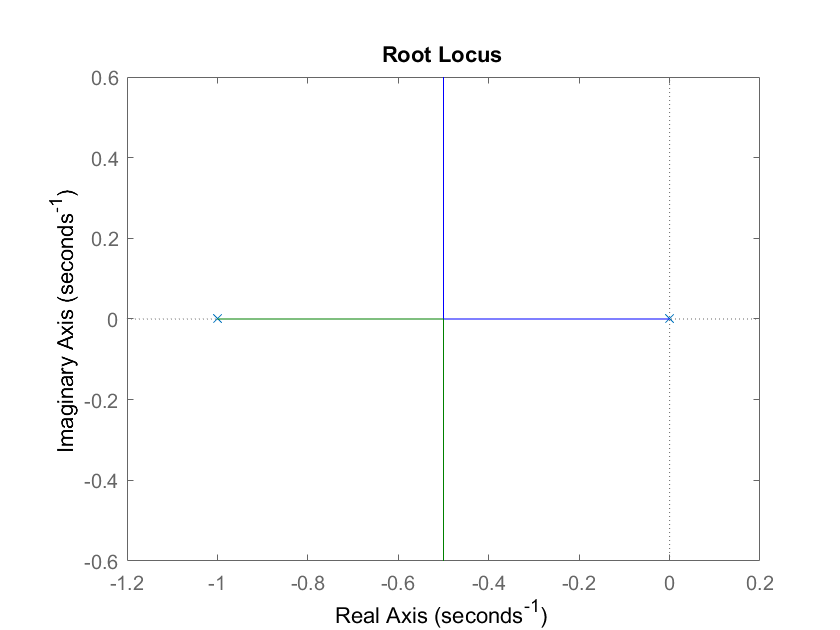

rlocus(P)

% T = 1-1/(1+P)
% step(T)

G_des = tf([1],[1 4 16])

G_des =
 
        1
  --------------
  s^2 + 4 s + 16
 
Continuous-time transfer function.



fprintf('-----Step response of Desired root----');

-----Step response of Desired root----

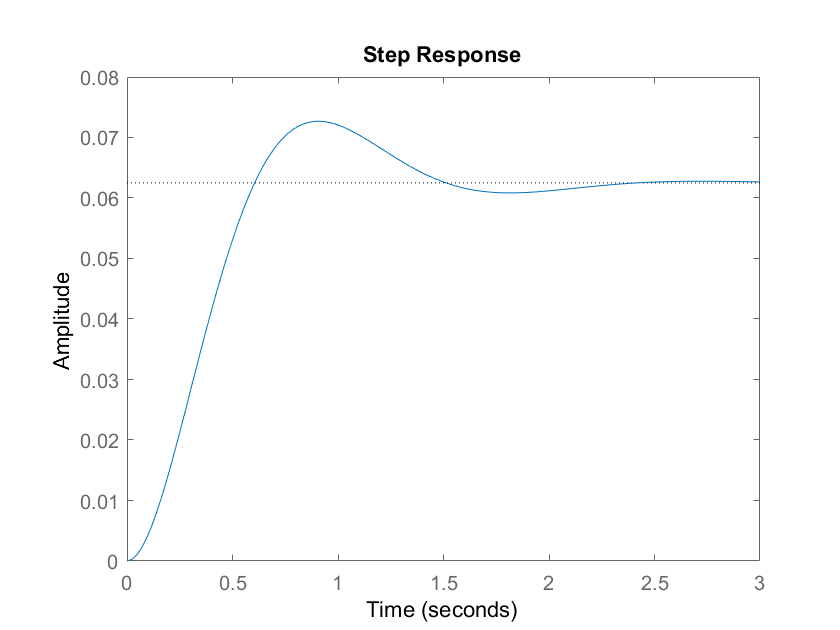

step(G_des);

stepinfo(G_des)

ans = struct with fields:
        RiseTime: 0.4098
    SettlingTime: 2.0190
     SettlingMin: 0.0582
     SettlingMax: 0.0727
       Overshoot: 16.2929
      Undershoot: 0
            Peak: 0.0727
        PeakTime: 0.8980



syms p;
p_sol = solve(2/3 * pi + (pi - atan(2*3^0.5)) + atan(2*3^0.5/(p-2)) == 4/3*pi,p)

$$p\_sol = \frac{2\,\sqrt{3}}{\tan\left(\frac{4\,\pi }{3}-\frac{138845495565775}{35184372088832}\right)}+2$$

p_s = double(p_sol)

p_s = 16.0000


s = tf('s');

G_o = tf([1,4],[1,1+p_s,p_s,0])

G_o =
 
         s + 4
  -------------------
  s^3 + 17 s^2 + 16 s
 
Continuous-time transfer function.



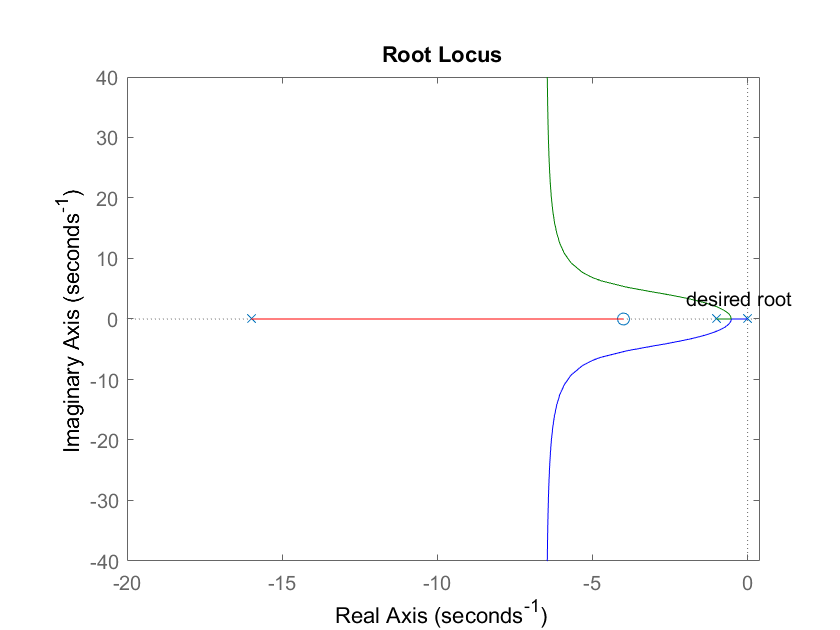

rlocus(G_o);
text(-2,2*3^0.5,'desired root');

% stepinfo(G_o)

fprintf('-----Bode Plot of Lead Compensator----')

-----Bode Plot of Lead Compensator----

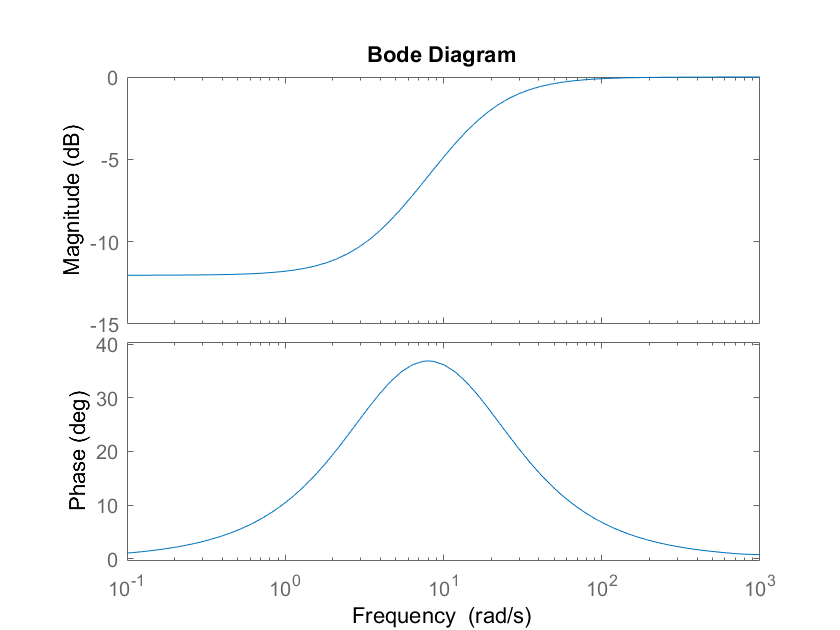

Hs = tf([1,4],[1,16]);
bode(Hs)


fprintf('----Bode Plot of S and T----');

----Bode Plot of S and T----

S = 1/(1+G_o)

S =
 
    s^3 + 17 s^2 + 16 s
  -----------------------
  s^3 + 17 s^2 + 17 s + 4
 
Continuous-time transfer function.



T = 1-S

T =
 
           s + 4
  -----------------------
  s^3 + 17 s^2 + 17 s + 4
 
Continuous-time transfer function.



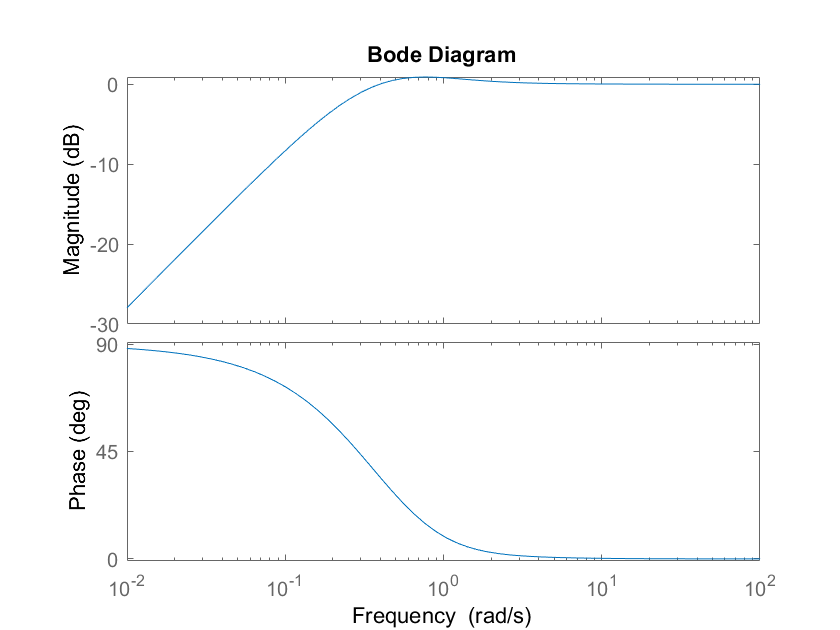


bode(S);

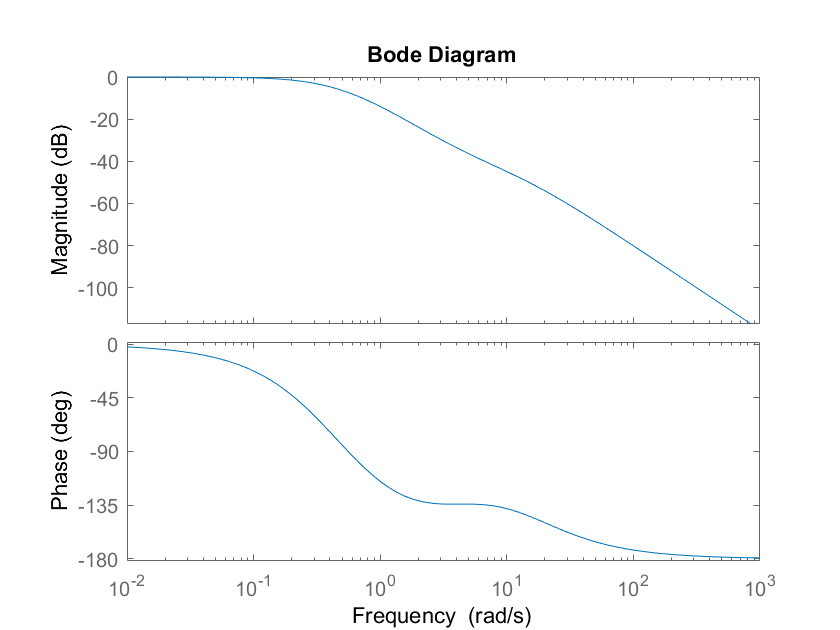

bode(T);


fprintf('----Gain and Phase Margin----')

----Gain and Phase Margin----

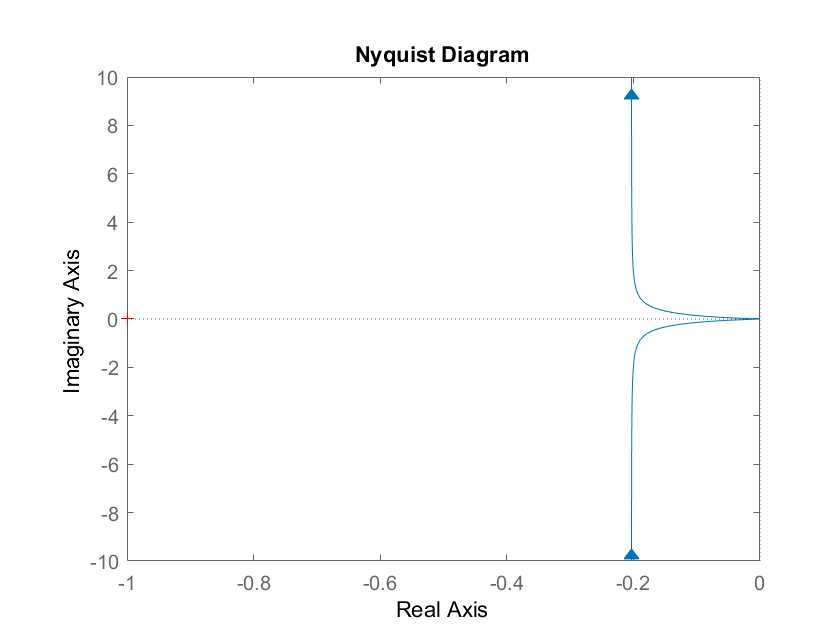

nyquist(G_o)

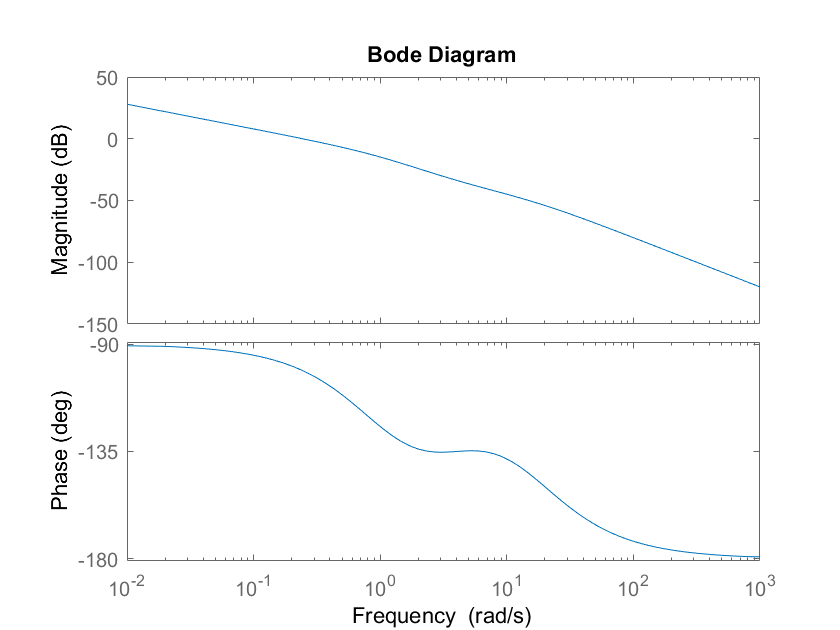

bode(G_o)